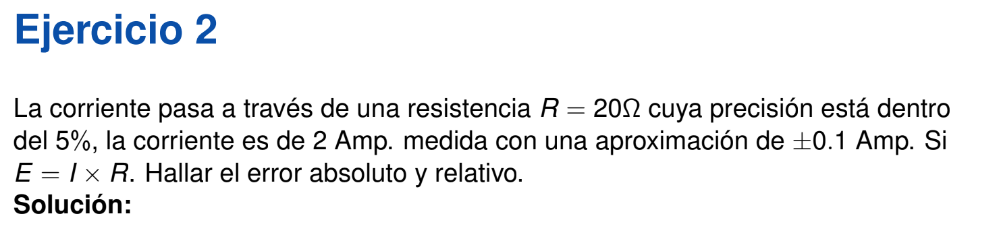

syms R I

%Funcion
E = @(I,R) I * R;

%Valores Iniciales
R_val = 20;
I_val = 2;

%Error Absolutto
eaR = 20 * 0.05;
eaI = 0.1;

%Derivada respecto a cada variable
dE_dR = matlabFunction(diff(E,R));
dE_dI = matlabFunction(diff(E,I));

%Valor absoluto de E
eaE = abs(dE_dR(I_val)) * eaR + abs(dE_dI(R_val ))  * eaI

eaE = 4

valorExactoE = E(I_val,R_val )

valorExactoE = 40

%Valor Relativo de E
erE = eaE/valorExactoE

erE = 0.1000